# Explore **ACTIVE** rotations applied to a BODY-FIXED frame

In this tutorial, we're going to explore the concept of **ACTIVE** rotation matrices. 

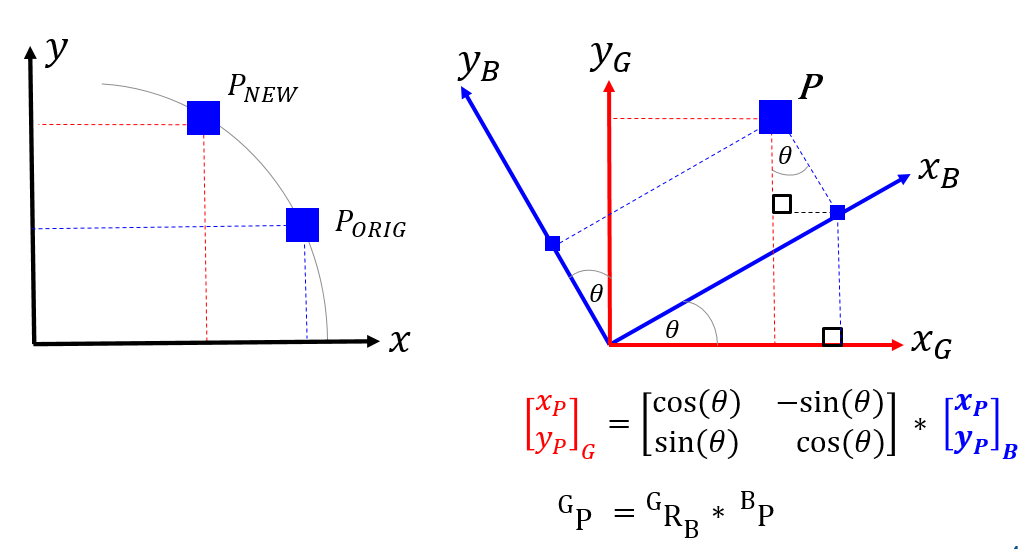

**Why are we doing this ?**

- Rotation matrices are used heavily in Mechanical, Robotic and Aeronautical engineering applications.

- Often students can get confused when they read the term "Rotation matrix".  In many/most cases, this confusion can be reduced by emphasizing a rotation matrix as being either PASSIVE or ACTIVE.

`Bradley Horton : 01-Mar-2016, bradley.horton@mathworks.com.au`

## Introduction:

Consider the scenario where we have an original data point $P_{ORIG}$ and we want to rotate this data point to a new location called $P_{NEW}$ . This scenario is shown below. We can think of this task in the following way:

- Imagine that we start with $P_{ORIG}$ and that this point is fixed ("glued") to a co-ordinate frame called the **B-frame**.

- We know the *(x,y) *co-ordinates of the point in this **B-fame** and refer to this as ${^BP}$

- We then rotate the **B-frame** relative to a fixed frame called the **G-frame**. Note that because point P is "glued" to the **B-frame**, the co-ordinates ${^BP}$ do not change while the **B-frame** is rotating.

We now want to now what the final co-ordinate of the point $P$ is relative to the fixed **G-frame, **ie: what is ${^GP}$ ?  This is also shown below:

  

An **ACTIVE** rotation matrix ${^GR_B}$, allows us to calculate the position of the new point relative to the G-frame, ie: ${^GP}$.  An example of a matrix equation that defines this **ACTIVE** rotation is defined below: 

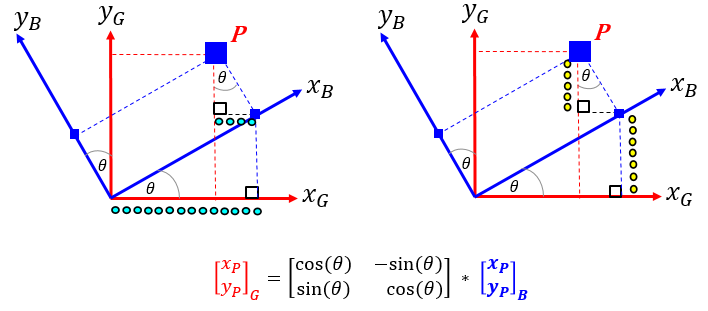

## A concrete example - part 1:

Consider the specific case of ${^BP} = \pmatrix{ 1 \cr 0 \cr 0} $ and a B-frame rotated by 45 degrees relative to Z axis of the  G-frame:

bP    = [1,0,0]';
alpha = 45*pi/180;

gRb   = [   cos(alpha), -sin(alpha),  0;
            sin(alpha),  cos(alpha),  0;
                     0,           0,  1];
       
gP = gRb * bP   

gP =     0.7071
    0.7071
         0


## A concrete example - part 2:

We can implement the formula for this ACTIVE rotation matrix ${^GR_B}$ into a MATLAB class called <`bh_rot_active_B2G_CLS`>.  This will allow us to reuse the formula over and over again. So repeating the previous example we have:

bP    = [1, 0, 0]';
alpha = 45*pi/180;
OBJ_AR = bh_rot_active_B2G_CLS({'D1Z'}, alpha, 'RADIANS');
gRb    = OBJ_AR.get_active_R1();
       
gP = gRb * bP 

gP =     0.7071
    0.7071
         0


## Recall our discussion on PASSIVE rotations

There is a special relationship between PASSIVE and ACTIVE rotation matrices, so let's first review what we know about PASSIVE rotation matrices. Say we have a fixed G-frame. We start by having our B-frame co-incident with G, and then we start to rotate the B-frame. Specifically, we're going to apply 3 LOCAL axes rotations which will result in a newly orientated frame called the B-frame.  Assume that we apply these 3 successive rotations in the following order:

- R1Z occurs 1st about the LOCAL **Z** body axis $(\phi)$, aka **YAW**

- R2Y occurs 2nd about the LOCAL **Y** body axis $(\theta)$, aka **PITCH**

- R3X occurs 3rd about the LOCAL **X** body axis $(\psi)$, aka **ROLL**

We can express a vector defined in the G-frame to it's corresponding description in the B-frame, using a sequence of **PASSIVE** rotation matrices, ie:


$$\bf ^Bv = R3X(\psi_x) \enspace \times \enspace 
R2Y(\theta_y) \enspace \times \enspace R1Z(\phi_z) \enspace \times \enspace {^Gv}$$


    OR, in a more compact form as:     $\bf ^Bv = {^BR_G} \enspace \times \enspace {^Gv}$      Where ${^BR_G}$ is the PASSIVE rotation matrix.

## Now define what we mean by ACTIVE rotations

Continuing on from the previous section, we can now write:

$\bf {^Gv}$** = **$R1Z(\phi_z)^{-1}$** *  **$R2Y(\theta_y)^{-1}$** *  **$R3X(\psi_x)^{-1}$** * **$\bf {^Bv}$

$\bf {^Gv}$** = **$R1Z(\phi_z)^{T}$**  *  **$R2Y(\theta_y)^{T}$**   *  **$R3X(\psi_x)^{T}$**  * **$\bf {^Bv}$

$\bf {^Gv}$** = **$R1Z(-\phi_z)$** *  **$R2Y(-\theta_y)$**   *  **$R3X(-\psi_x)$** * **$\bf {^Bv}$

If we now define the following **ACTIVE** rotation matrices:

- `a_R1Z(`$\phi_z$`) = `$R1Z(\phi_z)^{-1}$` = `$R1Z(- \phi_z)$

- `a_R2Y(`$\theta_y$`) = `$R2Y(\theta_y)^{-1}$` = `$R2Y(- \theta_y)$

- `a_R3X(`$\psi_x$`) = `$R3X(\psi_x)^{-1}$` = `$R3X(- \psi_x)$

Then we can write:

                                $\bf {^Gv}$` = a_R1Z``(`$\phi_z$`) * a_R2Y``(`$\theta_y$`) * a_R3``(`$\psi_x$`) * `$\bf {^Bv}$

Or in a more compact form:      $\bf {^Gv} = {^GR_B} \times {^Bv} $     Where ${^GR_B}$ is the ACTIVE rotation matrix.

It should be clear that :     ${^GR_B} = (^BR_G)^{-1}=(^BR_G)^T$

## Let's explore these ACTIVE rotations

Let's create on of those active rotation objects that we used earlier.  We'll create an object that implmenets the sequence:

- R1Z occurs 1st about the LOCAL **Z** body axis $(\phi)$, aka **YAW**

- R2Y occurs 2nd about the LOCAL **Y** body axis $(\theta)$, aka **PITCH**

- R3X occurs 3rd about the LOCAL **X** body axis $(\psi)$, aka **ROLL**

OBJ_A = bh_rot_active_B2G_CLS({'D1Z', 'D2Y', 'D3X'}, [sym('phi'), sym('theta'), sym('psi')], 'SYM')

OBJ_A =   bh_rot_active_B2G_CLS with properties:

        ang_units: SYM
    num_rotations: 3
          dir_1st: D1Z
          dir_2nd: D2Y
          dir_3rd: D3X
          ang_1st: [1x1 sym]
          ang_2nd: [1x1 sym]
          ang_3rd: [1x1 sym]


The symbolic ACTIVE  rotation matrices

aR1     = OBJ_A.get_active_R1

$$aR1 = \left(\begin{array}{ccc} \cos\left(\phi \right) & -\sin\left(\phi \right) & 0\\ \sin\left(\phi \right) & \cos\left(\phi \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

aR2     = OBJ_A.get_active_R2

$$aR2 = \left(\begin{array}{ccc} \cos\left(\theta \right) & 0 & \sin\left(\theta \right)\\ 0 & 1 & 0\\ -\sin\left(\theta \right) & 0 & \cos\left(\theta \right) \end{array}\right)$$

aR3     = OBJ_A.get_active_R3

$$aR3 = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\psi \right) & -\sin\left(\psi \right)\\ 0 & \sin\left(\psi \right) & \cos\left(\psi \right) \end{array}\right)$$

## Here are some compound ACTIVE rotation matrices - part 1

aR1R2    = aR1*aR2

$$aR1R2 = \left(\begin{array}{ccc} \cos\left(\phi \right)\,\cos\left(\theta \right) & -\sin\left(\phi \right) & \cos\left(\phi \right)\,\sin\left(\theta \right)\\ \cos\left(\theta \right)\,\sin\left(\phi \right) & \cos\left(\phi \right) & \sin\left(\phi \right)\,\sin\left(\theta \right)\\ -\sin\left(\theta \right) & 0 & \cos\left(\theta \right) \end{array}\right)$$

Note that "aR1 * R2" is the same thing as "get_active_R1R2()":

diff_mat = aR1R2 - OBJ_A.get_active_R1R2 % this should be a ZERO matrix

$$diff\_mat = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

## Here are some compound ACTIVE rotation matrices - part 2

aR1R2R3 = aR1*aR2*aR3

$$aR1R2R3 = \left(\begin{array}{ccc} \cos\left(\phi \right)\,\cos\left(\theta \right) & \cos\left(\phi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\sin\left(\phi \right) & \sin\left(\phi \right)\,\sin\left(\psi \right)+\cos\left(\phi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right)\\ \cos\left(\theta \right)\,\sin\left(\phi \right) & \cos\left(\phi \right)\,\cos\left(\psi \right)+\sin\left(\phi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\psi \right)\,\sin\left(\phi \right)\,\sin\left(\theta \right)-\cos\left(\phi \right)\,\sin\left(\psi \right)\\ -\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\psi \right) & \cos\left(\psi \right)\,\cos\left(\theta \right) \end{array}\right)$$

Note that "aR1 * R2 * aR3" is the same thing as "get_active_R1R2R3()":

diff_mat = aR1R2R3 - OBJ_A.get_active_R1R2R3 % this should be a ZERO matrix

$$diff\_mat = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

## Here is the ACTIVE rotation matrix $^{G}R_{B}$

Here is the compound ACTIVE rotation matrix:

gRb = aR1*aR2*aR3

$$gRb = \left(\begin{array}{ccc} \cos\left(\phi \right)\,\cos\left(\theta \right) & \cos\left(\phi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\sin\left(\phi \right) & \sin\left(\phi \right)\,\sin\left(\psi \right)+\cos\left(\phi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right)\\ \cos\left(\theta \right)\,\sin\left(\phi \right) & \cos\left(\phi \right)\,\cos\left(\psi \right)+\sin\left(\phi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\psi \right)\,\sin\left(\phi \right)\,\sin\left(\theta \right)-\cos\left(\phi \right)\,\sin\left(\psi \right)\\ -\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\psi \right) & \cos\left(\psi \right)\,\cos\left(\theta \right) \end{array}\right)$$

## Recall the PASSIVE rotation matrix $^{B}R_{G}$

Note how the inverse of the **ACTIVE** ${^GR_B}$ is just the **PASSIVE** ${^BR_G}$ which we computed during our discussion on PASSIVE rotations

bRg = inv(gRb);
simplify(bRg)

$$ans = \left(\begin{array}{ccc} \cos\left(\phi \right)\,\cos\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\phi \right) & -\sin\left(\theta \right)\\ \cos\left(\phi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\sin\left(\phi \right) & \cos\left(\phi \right)\,\cos\left(\psi \right)+\sin\left(\phi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\psi \right)\\ \sin\left(\phi \right)\,\sin\left(\psi \right)+\cos\left(\phi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\psi \right)\,\sin\left(\phi \right)\,\sin\left(\theta \right)-\cos\left(\phi \right)\,\sin\left(\psi \right) & \cos\left(\psi \right)\,\cos\left(\theta \right) \end{array}\right)$$

## Let's rotate an aeriel vehicle:

Now let's apply these ACTIVE rotation matrices to a "vehicle":

% this will be the "toy" system that we'll rotate in space
veh_OBJ = bh_vehicle_CLS()

veh_OBJ =   bh_vehicle_CLS with properties:

    FaceAlpha: 1
          gRb: [3x3 double]
           XL: [-2 2]
           YL: [-2 2]
           ZL: [-2 2]
      X_b_col: [18x1 double]
      Y_b_col: [18x1 double]
      Z_b_col: [18x1 double]
      X_g_col: [18x1 double]
      Y_g_col: [18x1 double]
      Z_g_col: [18x1 double]


Show the vehicle in it's original pose

figure();

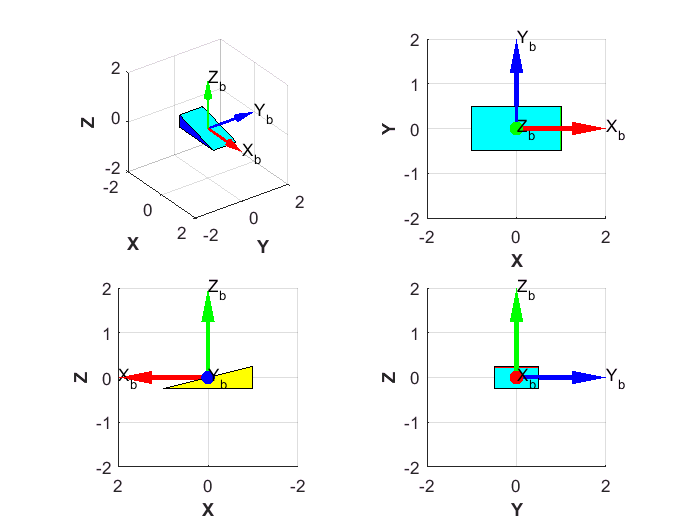

hax(1) = subplot(2,2,1);  veh_OBJ.plot_3D(hax(1));
hax(2) = subplot(2,2,2);  veh_OBJ.plot_XY(hax(2));  
hax(3) = subplot(2,2,3);  veh_OBJ.plot_XZ(hax(3));  
hax(4) = subplot(2,2,4);  veh_OBJ.plot_YZ(hax(4));

## Define the ACTIVE rotation sequence and angles

We'd like to subject the vehicle to a series of rotations applied to a body fixed co-ordinate frame attached to the vehicle.  Assume that we apply these 3 successive rotations in the following order:

- R1Z occurs 1st about the LOCAL **Z** body axis $(\phi)$, aka **YAW**

- R2Y occurs 2nd about the LOCAL **Y** body axis $(\theta)$, aka **PITCH**

- R3X occurs 3rd about the LOCAL **X** body axis $(\psi)$, aka **ROLL**

degs_yaw  = 90; 
degs_pitch= 30;
degs_roll = 60;

arot_OBJ  = bh_rot_active_B2G_CLS({'D1Z','D2Y','D3X'}, ...
                                  [degs_yaw, degs_pitch, degs_roll], ...
                                  'DEGREES')

arot_OBJ =   bh_rot_active_B2G_CLS with properties:

        ang_units: DEGREES
    num_rotations: 3
          dir_1st: D1Z
          dir_2nd: D2Y
          dir_3rd: D3X
          ang_1st: 90
          ang_2nd: 30
          ang_3rd: 60


## Now apply this ACTIVE rotation sequence to the vehicle

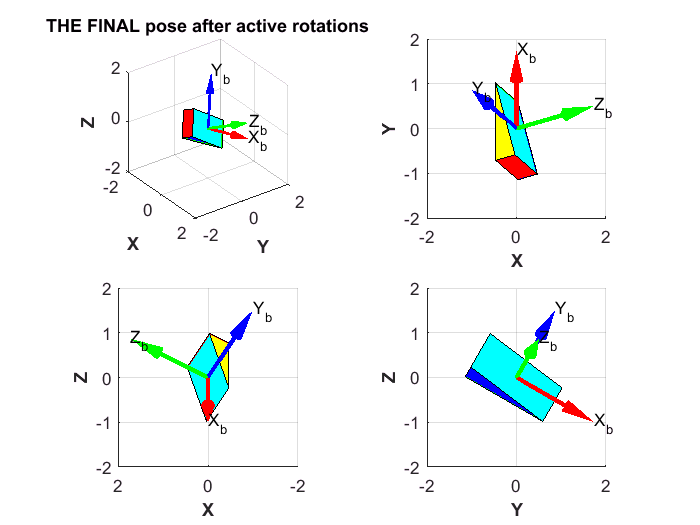

% get each of the active rotation matrices
aR1 = arot_OBJ.get_active_R1();
aR2 = arot_OBJ.get_active_R2();
aR3 = arot_OBJ.get_active_R3();

% chain them together in the correct ACTIVE order
aR1R2R3 = aR1 * aR2 * aR3;

% get the B frame geometry data of the vehicle
[X,Y,Z] = veh_OBJ.get_B_XYZ();
v_mat   = [ X(:), Y(:), Z(:) ]';  % a 3xN matrix

% now apply the complete ACTIVE rotation matrix to our vehicle data
new_XYZ = aR1R2R3 * v_mat;

% store this new rotated vehicle data
veh_OBJ       =  veh_OBJ.set_G_XYZ(new_XYZ(1,:)', new_XYZ(2,:)', new_XYZ(3,:)');

% store the DCM so that we can draw the body fixed frame arrows
veh_OBJ.gRb = arot_OBJ.get_active_R;

% plot the new rotated vehicle
figure();
hax(1) = subplot(2,2,1);  veh_OBJ.plot_3D(hax(1));
hax(2) = subplot(2,2,2);  veh_OBJ.plot_XY(hax(2));  
hax(3) = subplot(2,2,3);  veh_OBJ.plot_XZ(hax(3));  
hax(4) = subplot(2,2,4);  veh_OBJ.plot_YZ(hax(4));  
title(hax(1), 'THE FINAL pose after active rotations')

## REPEAT what we just did ... **BUT** let's show the progressive rotations

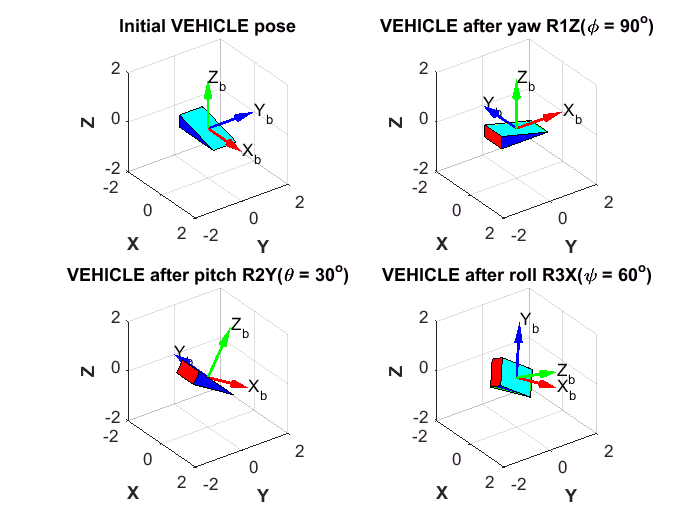

veh_OBJ = bh_vehicle_CLS();
figure();
clear hax

% Here's the vehicle in its ORIGINAL pose
hax(1) = subplot(2,2,1);  veh_OBJ.plot_3D(hax(1));
title(hax(1),'Initial VEHICLE pose')

% apply the 1st active rotation
clear veh_OBJ
veh_OBJ = bh_vehicle_CLS();                % ORIG pose is starting point
V_3xN   =  veh_OBJ.get_B_XYZ_3xN();        % get current vehicle data
new_XYZ = arot_OBJ.apply_active_R1(V_3xN); % apply the rotation
veh_OBJ =  veh_OBJ.set_G_XYZ(new_XYZ(1,:)', new_XYZ(2,:)', new_XYZ(3,:)');
gRb     = arot_OBJ.get_active_R1();        % get and store the DCM 
veh_OBJ.gRb = gRb;
% update the vehicle's PLOT
hax(2)  = subplot(2,2,2);  veh_OBJ.plot_3D(hax(2));
str     = sprintf('VEHICLE after yaw R1Z(\\phi = %d^o)',degs_yaw);
title(hax(2),str)

% apply the 2nd active multiplication
clear veh_OBJ
veh_OBJ = bh_vehicle_CLS();                  % ORIG pose is starting point
V_3xN   =  veh_OBJ.get_B_XYZ_3xN();          % get current vehicle data
new_XYZ = arot_OBJ.apply_active_R1R2(V_3xN); % apply the rotation
veh_OBJ =  veh_OBJ.set_G_XYZ(new_XYZ(1,:)', new_XYZ(2,:)', new_XYZ(3,:)');
gRb     = arot_OBJ.get_active_R1R2();
veh_OBJ.gRb = gRb;
% update the vehicle's PLOT
hax(3)  = subplot(2,2,3);  veh_OBJ.plot_3D(hax(3));
str     = sprintf('VEHICLE after pitch R2Y(\\theta = %d^o)',degs_pitch);
title(hax(3),str)

% apply the 3rd active multiplication
clear veh_OBJ
veh_OBJ = bh_vehicle_CLS();                    % ORIG pose is starting point
V_3xN   =  veh_OBJ.get_B_XYZ_3xN();            % get current vehicle data
new_XYZ = arot_OBJ.apply_active_R1R2R3(V_3xN); % apply the rotation
veh_OBJ =  veh_OBJ.set_G_XYZ(new_XYZ(1,:)', new_XYZ(2,:)', new_XYZ(3,:)');
gRb     = arot_OBJ.get_active_R1R2R3();
veh_OBJ.gRb = gRb;   
% update the vehicle's PLOT
hax(4)  = subplot(2,2,4);   veh_OBJ.plot_3D(hax(4));
str     = sprintf('VEHICLE after roll R3X(\\psi = %d^o)',degs_roll);
title(hax(4),str)

# Next steps:

Animating what we've just done.  If you evaluate the following code in the MATLAB command window, you'll see an animation of our vehicle:

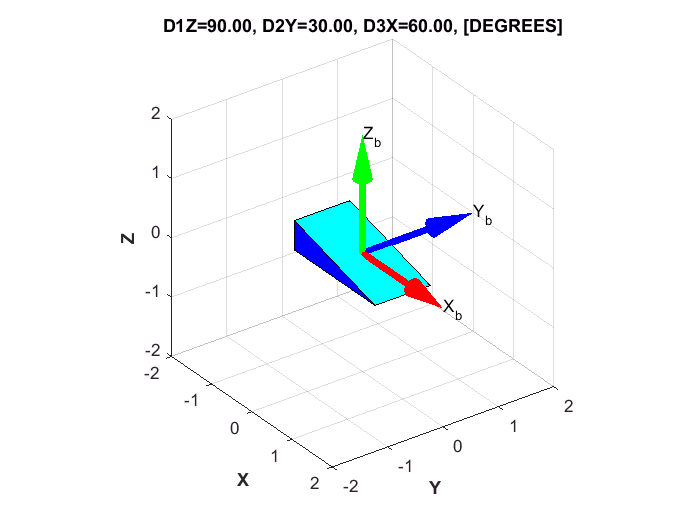

% Create an ACTIVE rotation object

degs_yaw  = 90; 
degs_pitch= 30;
degs_roll = 60;
arot_OBJ  = bh_rot_active_B2G_CLS({'D1Z','D2Y','D3X'}, ...
                                  [degs_yaw, degs_pitch, degs_roll], ...
                                  'DEGREES');
% create a figure
figure();
hax = axes;
desc_str = arot_OBJ.get_description();
title(hax, desc_str);

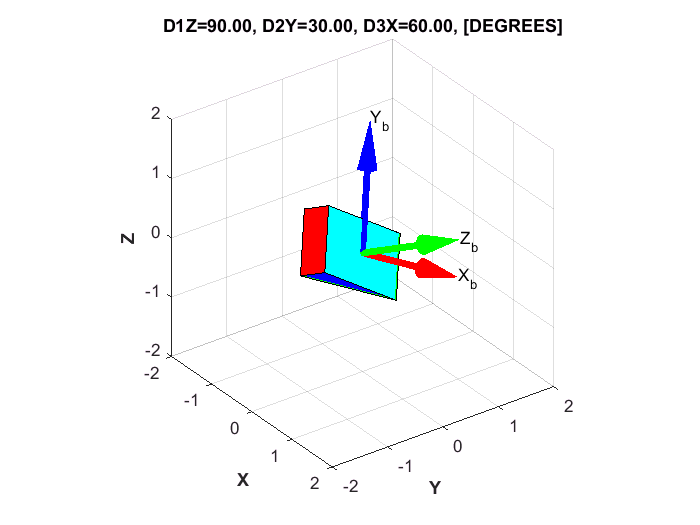


% create an ANIMATION
veh_OBJ = veh_OBJ.rotate_and_animate(arot_OBJ, hax);